**Exercise 001**

Generate M3 and M5 using a loop structure

M3 = ones(10,10);
disp(M3)

M3= zeros(10,10);
for ii=1:10
    for jj=1:10
        M3(ii,jj) = 1;
    end
end

M3= zeros(10,10);
for ii=1:100
    M3(ii) = 1;
end

M3= zeros(10,10);
M3(:) = 1;

M5 = eye(5,5);
disp(M5)

M5 = zeros(5, 5);
for ii=1:5
    M5(ii,ii) = 1;
end

#### Exercise 002

Write a code to generate the following matrix

    0     1     0     0     0     0

    0     0     1     0     0     0

    0     0     0     1     0     0

    0     0     0     0     1     0

    0     0     0     0     0     1

    0     0     0     0     0     0


e2 = zeros(6,6);

for ii=1:5
    e2(ii,ii+1) = 1;
    
end
e2

e2 =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0



diag(ones(1, 5), 1)

ans =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0


diag(ones(1, 4), 2)

ans =      0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0


#### Exercise 003

Write a code to generate M1~M9

(a) You can use for-loop(s) if needed.

(b) You only use the functions above (Do not use a loop structure).

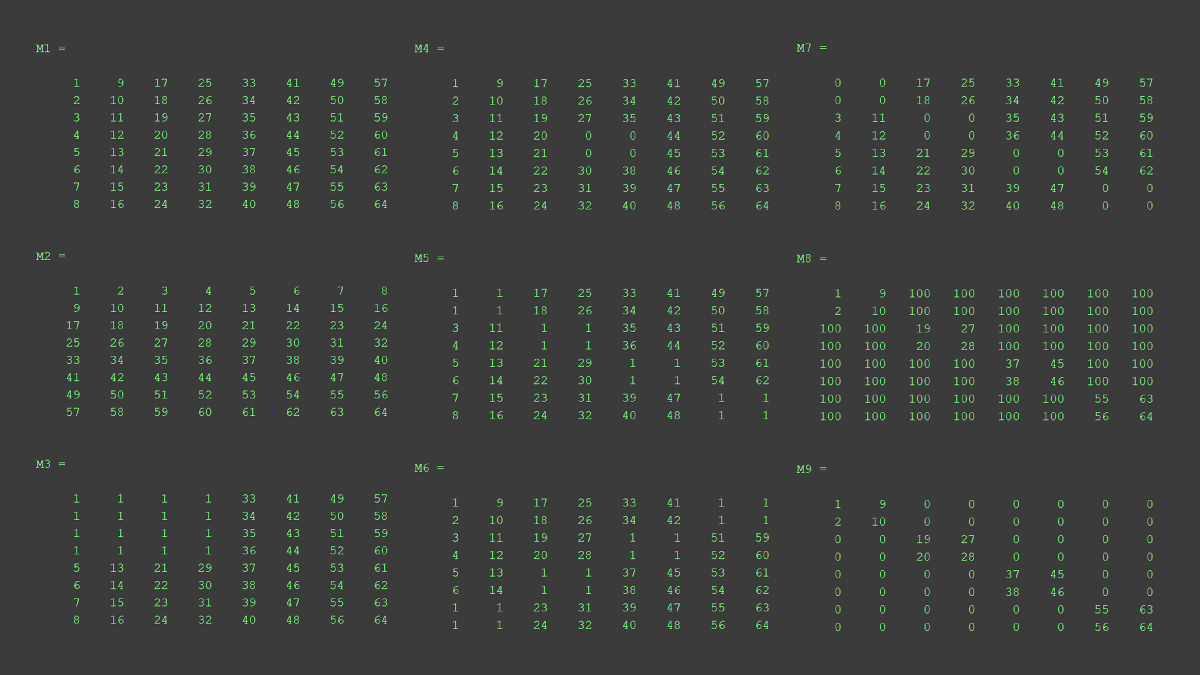

vec = 1:64;
M1 = reshape(vec, 8, 8);

M2 = M1'

M2 =      1     2     3     4     5     6     7     8
     9    10    11    12    13    14    15    16
    17    18    19    20    21    22    23    24
    25    26    27    28    29    30    31    32
    33    34    35    36    37    38    39    40
    41    42    43    44    45    46    47    48
    49    50    51    52    53    54    55    56
    57    58    59    60    61    62    63    64



M3 = M1;
M3(1:4, 1:4) = 1; 

M4 = M1;
M4(4:5,4:5)= 0

M4 =      1     9    17    25    33    41    49    57
     2    10    18    26    34    42    50    58
     3    11    19    27    35    43    51    59
     4    12    20     0     0    44    52    60
     5    13    21     0     0    45    53    61
     6    14    22    30    38    46    54    62
     7    15    23    31    39    47    55    63
     8    16    24    32    40    48    56    64



A = repelem(eye(2,2), 2, 2)

A =      1     1     0     0
     1     1     0     0
     0     0     1     1
     0     0     1     1



mask = [A zeros(4, 4); zeros(4,4) A]

mask =      1     1     0     0     0     0     0     0
     1     1     0     0     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     1     1


M5 = M1;
M5 = mask + M5.*~mask

M5 =      1     1    17    25    33    41    49    57
     1     1    18    26    34    42    50    58
     3    11     1     1    35    43    51    59
     4    12     1     1    36    44    52    60
     5    13    21    29     1     1    53    61
     6    14    22    30     1     1    54    62
     7    15    23    31    39    47     1     1
     8    16    24    32    40    48     1     1



M5 = M1;
M5(logical(mask)) = 1

M5 =      1     1    17    25    33    41    49    57
     1     1    18    26    34    42    50    58
     3    11     1     1    35    43    51    59
     4    12     1     1    36    44    52    60
     5    13    21    29     1     1    53    61
     6    14    22    30     1     1    54    62
     7    15    23    31    39    47     1     1
     8    16    24    32    40    48     1     1



M6 = M1;
mask = fliplr(mask);
M6 = mask + M6.*~mask

M6 =      1     9    17    25    33    41     1     1
     2    10    18    26    34    42     1     1
     3    11    19    27     1     1    51    59
     4    12    20    28     1     1    52    60
     5    13     1     1    37    45    53    61
     6    14     1     1    38    46    54    62
     1     1    23    31    39    47    55    63
     1     1    24    32    40    48    56    64



mask = [A zeros(4, 4); zeros(4,4) A]

mask =      1     1     0     0     0     0     0     0
     1     1     0     0     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     1     1


M9 = M1;
M9(~mask) = 0

M9 =      1     9     0     0     0     0     0     0
     2    10     0     0     0     0     0     0
     0     0    19    27     0     0     0     0
     0     0    20    28     0     0     0     0
     0     0     0     0    37    45     0     0
     0     0     0     0    38    46     0     0
     0     0     0     0     0     0    55    63
     0     0     0     0     0     0    56    64


#### Exercise 004

- Read a 'coloredChips.png' image (run imread('coloredChips.png'))

- Find a location(s) of a RGB pixel in the image that has a value ranging from [150 0 0] to [255 100 100]. This means the ranges of R, G, and B are (150 255), (0 100), (0 100), respectively. 

- Make a new img where the pixels that do not satisfy the above conditions set to zeros.

- Show the new img

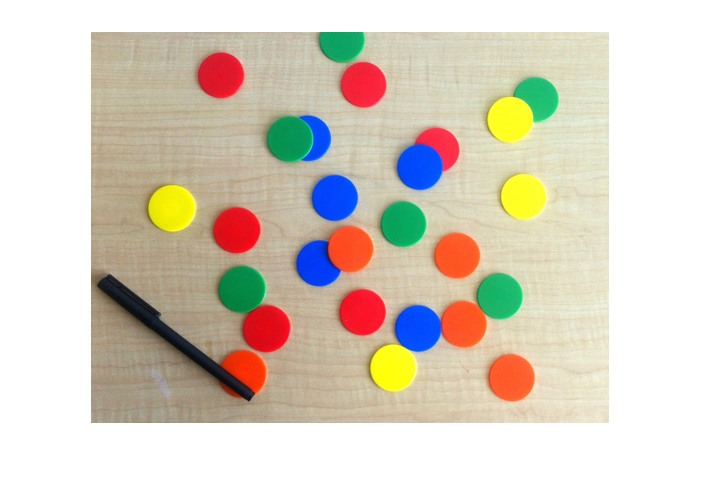

img = imread('coloredChips.png');
imshow(img)

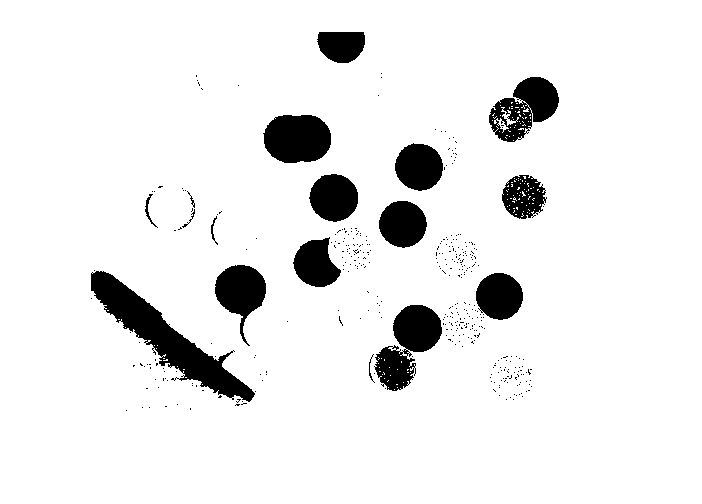


mask = zeros(size(img));

mask(:,:,1) = img(:,:,1)>150 & img(:,:,1)<255;
mask(:,:,2) = img(:,:,2)>0 & img(:,:,2)<100;
mask(:,:,3) = img(:,:,3)>0 & img(:,:,3)<100;

imshow(mask(:,:,1))

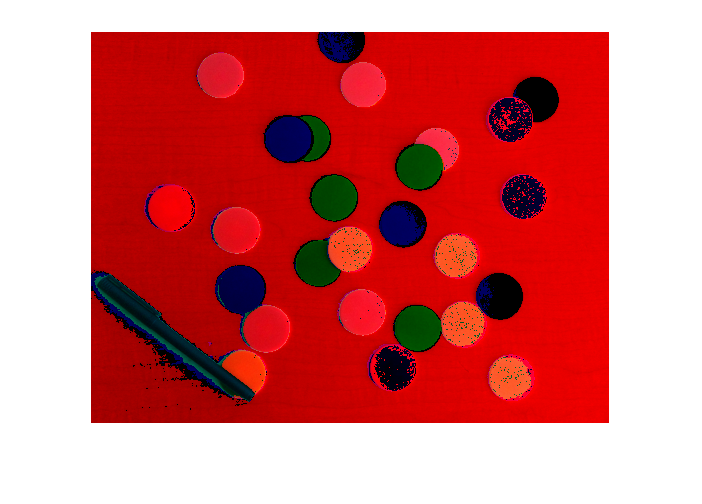


img(~mask) = 0;

imshow(img)